# System Identification (SI) for Narnia Testing Chamber

clear; clc;
data_dir = "C:\Users\hdt.OJ\OneDrive - OJ Electronics A S\Thesis\report\data\Test 6";

## Active cooling data

baselog_AC_file = data_dir + "\BaseLog-2024-03-19T152053-ActiveCooling.csv";
baselog_AC_data = loadDataSource(baselog_AC_file);

modblog_AC_file = data_dir + "\ModbusGUI-Log-2024-03-19T152042-ActiveCooling.csv";
modblog_AC_data = loadDataSource(modblog_AC_file);
modblog_AC_data.regulation_relay_state(:) = 0;
AC_data = innerjoin(modblog_AC_data,baselog_AC_data,"LeftKeys","TimeStamp","RightKeys","timestamp")

AC_data = 67174×30 table
           TimeStamp           regulation_relay_state    regulation_setpoint    pwm_info_pwm_period    pwm_info_pwm_step    pwm_info_period_length_seconds    pwm_info_pulse_counter    temperature_ambient    temperature_floor    count    sec    nu     RefFloor__CG0_    RefRoom__CG1_    RegRoom180cm__CG2_    RefTopFloor__CG3_    AirInHouse__CG4_    AirOutHouse__CG5_    TS0    TS1    TS2    TS3    TS4    TS5    Krap_Short    Krap_byte    Heat__VDC0_    Cool__VDC1_    Krap_Short1  

figure("Name", "Active Cooling");
% tiledlayout(2,1);
% nexttile;
hold on;
plot(AC_data.temperature_ambient);
plot(AC_data.temperature_floor);
plot(AC_data.count, AC_data.RefFloor__CG0_/10);
plot(AC_data.count, AC_data.RefRoom__CG1_/10);
plot(AC_data.count, AC_data.RegRoom180cm__CG2_/10);
plot(AC_data.count, AC_data.RefTopFloor__CG3_/10);
plot(AC_data.count, AC_data.AirInHouse__CG4_/10);
plot(AC_data.count, AC_data.AirOutHouse__CG5_/10);
legend("Air 100cm", "Floor 1", "Floor 2", "Air 140", "Air 180", "Top Floor", "Outside 1", "Outside 2");
ylabel("Temperature (°C)");
xlabel("Time (s)");
fontsize(22,"points");
% nexttile;
% plot(AC_data.regulation_relay_state);
% legend("relay state");
hold off;

## Heating data

baselog_He_file = data_dir + "\BaseLog-2024-03-20T100744-Heating.csv";
baselog_He_data = loadDataSource(baselog_He_file);

modblog_He_file = data_dir + "\ModbusGUI-Log-2024-03-20T100738-Heating.csv";
modblog_He_data = loadDataSource(modblog_He_file);
He_data = innerjoin(modblog_He_data,baselog_He_data,"LeftKeys","TimeStamp","RightKeys","timestamp")

He_data = 12316×32 table
           TimeStamp           regulation_relay_state    regulation_setpoint    regulation_output    pwm_info_pwm_step    pwm_info_period_length_seconds    pwm_info_pulse_counter    pwm_info_period_length_seconds_1    pwm_info_pulse_target    temperature_floor    temperature_ambient    count    sec    nu     RefFloor__CG0_    RefRoom__CG1_    RegRoom180cm__CG2_    RefTopFloor__CG3_    AirInHouse__CG4_    AirOutHouse__CG5_    TS0    TS1    TS2    TS3    TS4    TS5    Krap_Short    Krap_byte    <

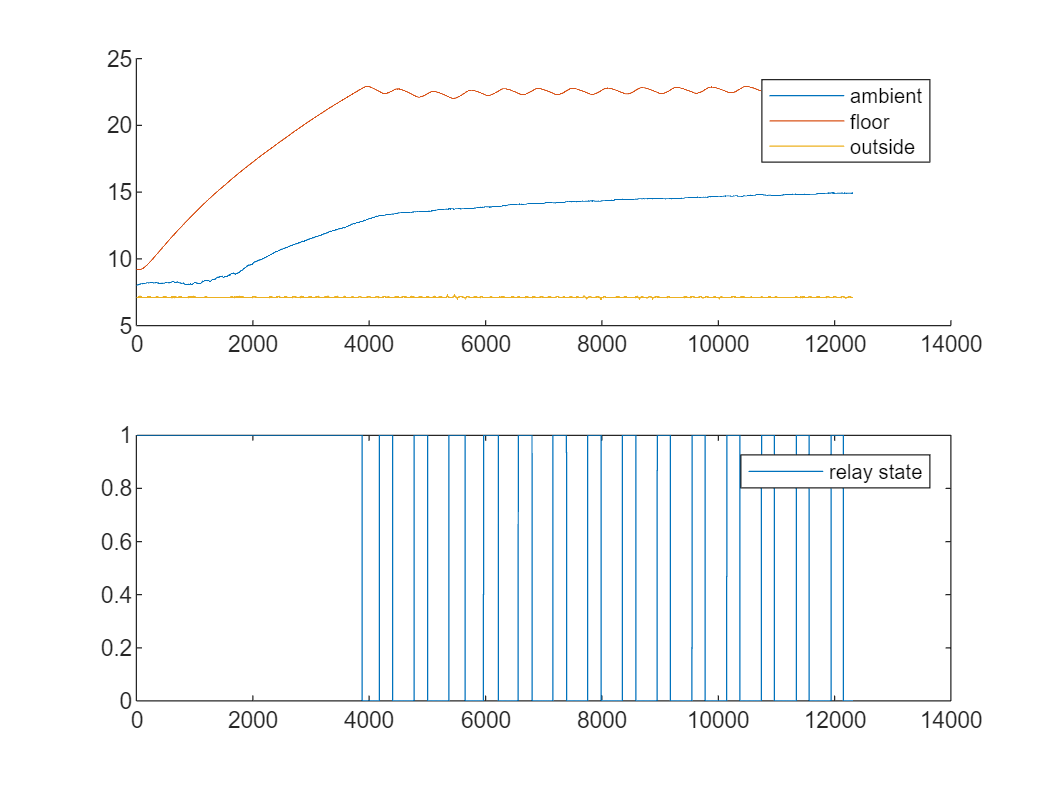

figure("Name","Heating");
tiledlayout(2,1);
nexttile;
hold on;
plot(He_data.temperature_ambient);
plot(He_data.temperature_floor);
plot(He_data.AirInHouse__CG4_/10);
legend("ambient", "floor", "outside");

nexttile;
plot(He_data.regulation_relay_state);
legend("relay state");
hold off;

## Combine active cooling with heating

T_a = vertcat(AC_data.temperature_ambient, He_data.temperature_ambient);
T_f = vertcat(AC_data.temperature_floor, He_data.temperature_floor);
T_o = vertcat(AC_data.AirInHouse__CG4_/10, He_data.AirInHouse__CG4_/10);
u = vertcat(AC_data.regulation_relay_state, He_data.regulation_relay_state*480);
t = vertcat(AC_data.TimeStamp, He_data.TimeStamp);
% Generate the main training dataset
full_set = table(t, u, T_f, T_a, T_o);

## Export data to vector image for Latex report

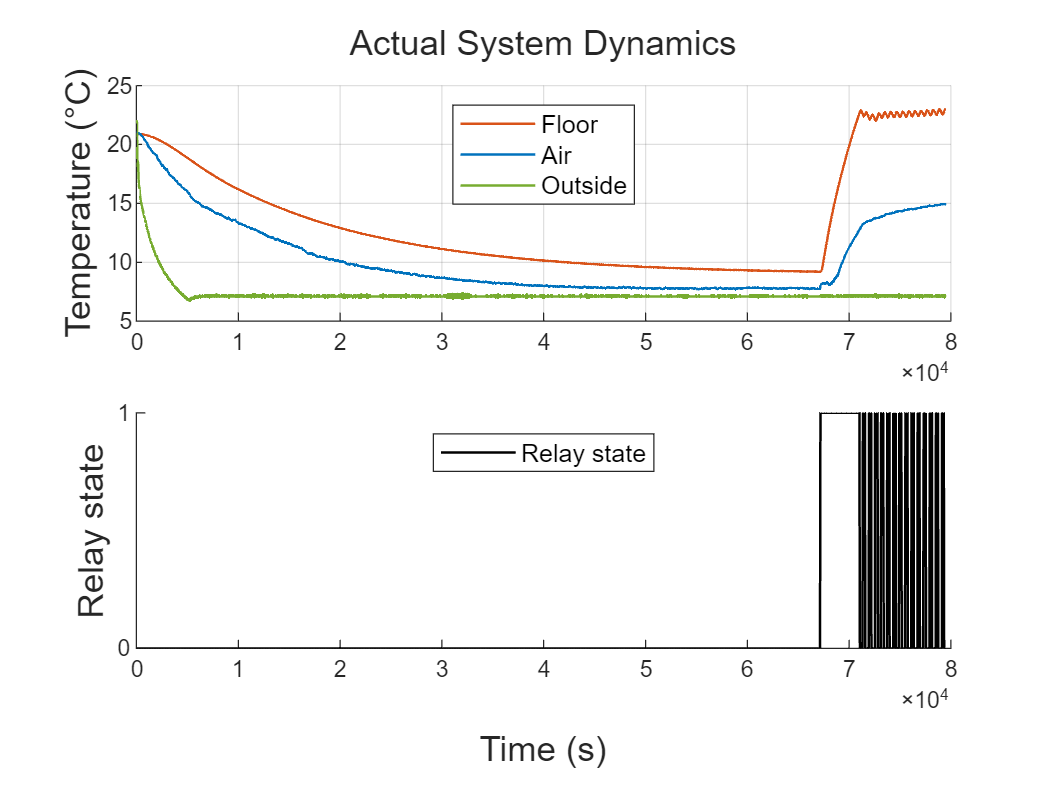

export_system_dynamics("Actual System Dynamics", ...
    T_a,...
    T_f,...
    T_o,...
    u/480, 'north');

## Start fitting with a grey model

It is better to use this whole set of "test 6" to train the model and use other "test x" to validate it. Set global samplint time $T_s$.

Ts = 1; %1 second

split_idx = 71000;
fit_set = full_set(1:split_idx,:);
fit_data = iddata([fit_set.T_f, fit_set.T_a], ...
    [fit_set.u, fit_set.T_o], ...
    Ts, ...
    'TimeUnit', 'seconds', ...
    'InputName', {'Electrical power', 'Outside temperature'}, ...
    'OutputName', {'Floor temperature', 'Air temperature'});

val_set = full_set(split_idx+1:end,:);
val_data = iddata([val_set.T_f, val_set.T_a], ...
    [val_set.u, val_set.T_o], ...
    Ts, ...
    'TimeUnit', 'seconds', ...
    'InputName', {'Electrical power', 'Outside temperature'}, ...
    'OutputName', {'Floor temperature', 'Air temperature'});

full_data = iddata([full_set.T_f, full_set.T_a], ...
    [full_set.u, full_set.T_o], ...
    Ts, ...
    'TimeUnit', 'seconds', ...
    'InputName', {'Electrical power', 'Outside temperature'}, ...
    'OutputName', {'Floor temperature', 'Air temperature'});

The physics model of Narnia, an enclosed chamber, is:


$$\pmatrix{
  \dot{T}_a \cr
  \dot{T}_f 
} = \pmatrix{
  -\frac{k_f A_f}{d_f m_a C_a} - \frac{k_w A_w}{d_w m_a C_a} & \frac{k_f A_f}{d_f m_a C_a} \cr
  \frac{k_f A_f}{d_f m_c C_f} & -\frac{k_f A_f}{d_f m_c C_f}
} \pmatrix{
  T_a \cr
  T_f
} + \pmatrix{
  0 \cr
  \frac{1}{m_f C_f}
}u + \pmatrix{
  \frac{k_w A_w}{d_w m_a C_a} \cr
  0
}T_e$$



$$\textbf{y} = \pmatrix{
  1 & 0 \cr
  0 & 1}
\textbf{x} = \pmatrix{
  T_A \cr
  T_F
}$$


Let $\text{par(1)} = \frac{1}{m_f C_f};
~~ \text{par(2)} = \frac{k_f A_f}{d_f};
~~ \text{par(3)} = \frac{1}{m_a C_a};
~~ \text{par(4)} = \frac{k_w A_w}{d_w}$

% Initial values derived from physics and my assumption
run("estim_by_physics.mlx");
% par1 = 1/(m_f*C_f);
% par2 = (k_f*A_f)/d_f;
% par3 = 1/(m_a*C_a);
% par4 = (k_w*A_w)/d_w;
pars = {'par1',par1; 'par2',par2; 'par3',par3; 'par4',par4};

model_init = idgrey('myfunc',pars,'c'); %Continuous time
opt = greyestOptions('InitialState',[fit_set.T_a(1); fit_set.T_f(1)],...
    'DisturbanceModel','none',...
    'Display','on');

model_est = greyest(fit_data, model_init, opt);

## Prepare validation data

baselog_NC_file = data_dir + "\BaseLog-2024-03-20T134102-NaturalCooling.csv";
baselog_NC_data = loadDataSource(baselog_NC_file);

modblog_NC_file = data_dir + "\ModbusGUI-Log-2024-03-20T134038-NaturalCooling.csv";
modblog_NC_data = loadDataSource(modblog_NC_file);
modblog_NC_data.regulation_relay_state(1:end) = 0;
NC_data = innerjoin(modblog_NC_data,baselog_NC_data,"LeftKeys","TimeStamp","RightKeys","timestamp")

NC_data = 75294×32 table
           TimeStamp           regulation_relay_state    regulation_setpoint    regulation_output    pwm_info_pwm_step    pwm_info_period_length_seconds    pwm_info_pulse_counter    pwm_info_period_length_seconds_1    pwm_info_pulse_target    temperature_floor    temperature_ambient    count    sec    nu     RefFloor__CG0_    RefRoom__CG1_    RegRoom180cm__CG2_    RefTopFloor__CG3_    AirInHouse__CG4_    AirOutHouse__CG5_    TS0    TS1    TS2    TS3    TS4    TS5    Krap_Short    Krap_byte    <

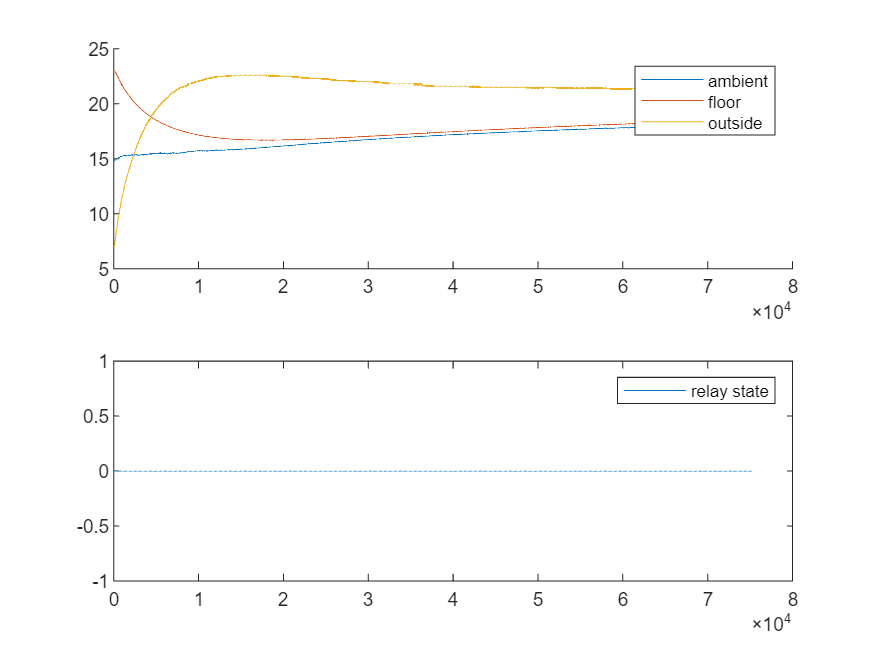

figure("Name","Natural Cooling");
tiledlayout(2,1);
nexttile;
hold on;
plot(NC_data.temperature_ambient);
plot(NC_data.temperature_floor);
plot(NC_data.AirInHouse__CG4_/10);
legend("ambient", "floor", "outside");

nexttile;
plot(NC_data.regulation_relay_state*480);
legend("relay state");
hold off;

val_data_2 = iddata([NC_data.temperature_floor, NC_data.temperature_ambient], ...
    [NC_data.regulation_relay_state*480, NC_data.AirInHouse__CG4_/10], ...
    1, ...
    'TimeUnit', 'seconds', ...
    'InputName', {'Electrical power', 'Outside temperature'}, ...
    'OutputName', {'Floor temperature', 'Air temperature'});

## Validate estimated models

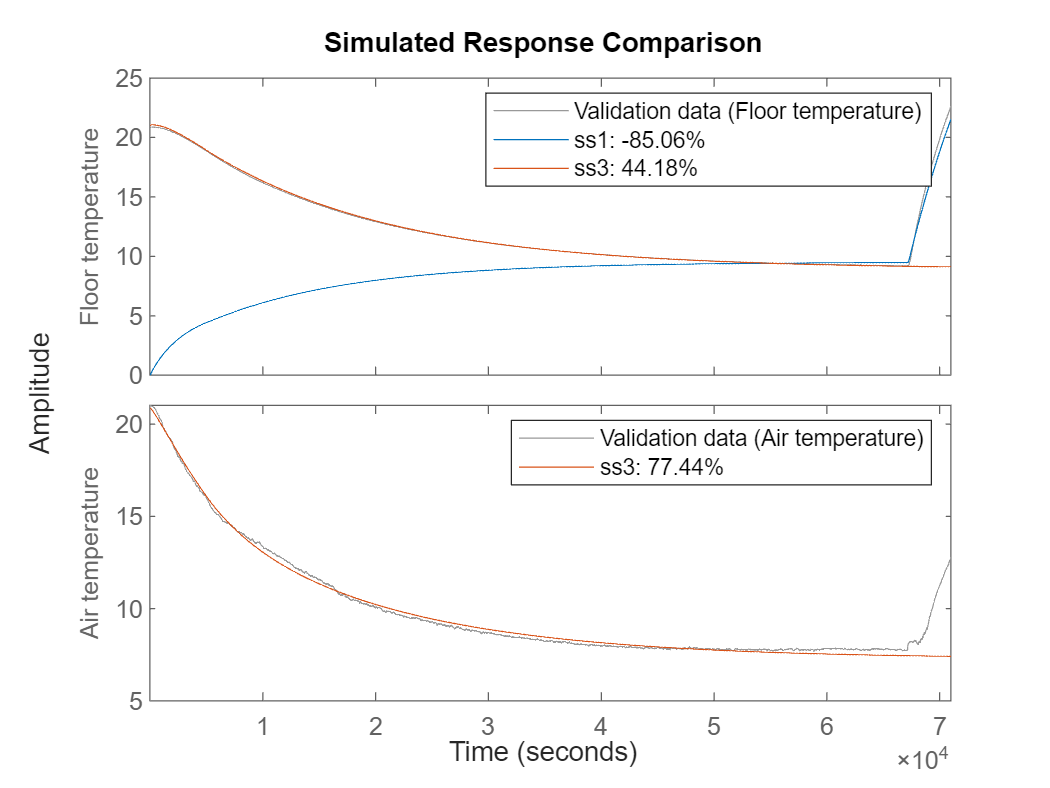

comp_opts = compareOptions();
% init_cond = initialCondition(model_est.A,[fit_set.T_f(1); fit_set.T_a(1)],model_est.C,0);
comp_opts.InitialCondition = [fit_set.T_a(1); fit_set.T_f(1)];
compare(fit_data, ss1, ss3, comp_opts);